clc
clear all
close all

## 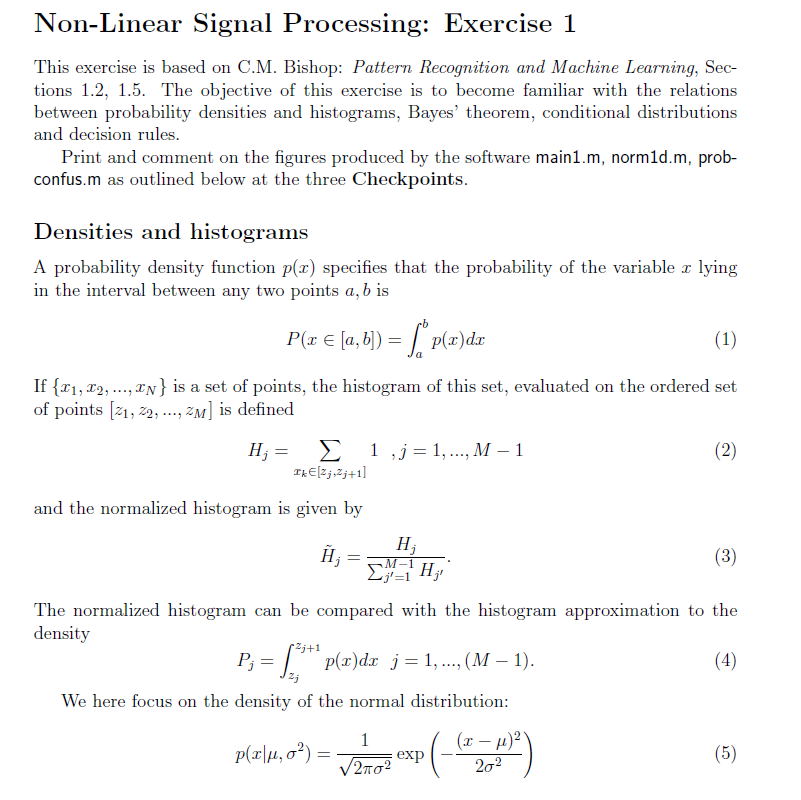

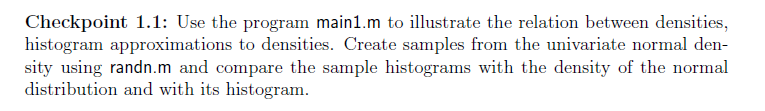

Firstly, we are going to determine the values of the parameters of the univariate normal densities.

mu=0.0;       % true mean value
sigma2=1.0;   % true variance
xmin=-5.0;    % min x value
xmax=5.0;     % max x value
Npdf=100;        % number of points in density
dx=0.4;       % bin width for histogram

Once the values of the parameters are known it is possible to obtain the values of the distribution using the help of the provided function norm1d.

[x1,p1,x2,p2]=norm1d(mu,sigma2,xmin,xmax,Npdf,dx);

The values returned by this function are as follows:

- x1: The Npdf points in the x axis of the distribution in between xmin and xmax 

- p1: The values of the distribution for each value of x1 (f(x1))

- x2: X values of the density for the histogram (the number depends on the "width" of the bars i.e. dx )

- p2: The y values of the histogram for x2

Once this values are understood, we can plot the results. 

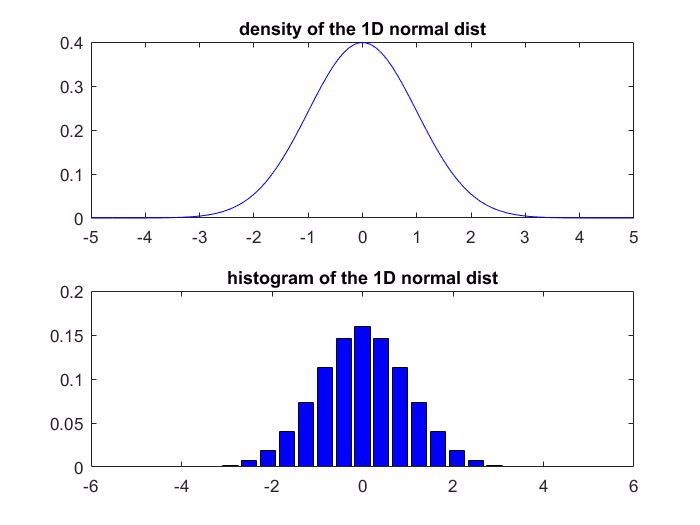

figure(1), subplot(2,1,1), plot(x1,p1,'b'), title('density of the 1D normal dist')
figure(1), subplot(2,1,2), bar(x2,p2,'b'), title('histogram of the 1D normal dist')

Now we are going to try to replicate this plots but in this case using some random numbers out of the matlab function randn(), which provides some random numbers normalized for mean=0 and sigma=1. 

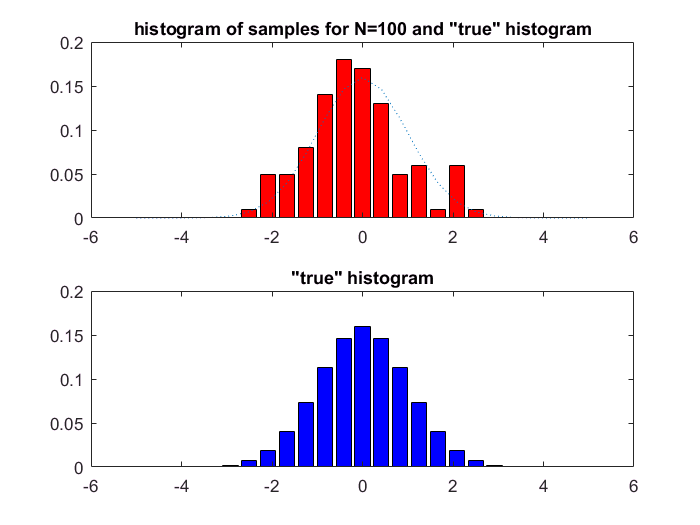

N=100; % number of samples
y1=sqrt(sigma2)*randn(N,1)+mu*ones(N,1);
y2=hist(y1,x2);
y2=y2/sum(y2);
figure(2), subplot(2,1,1),  bar(x2,y2,'r'),hold on, plot(x2,p2,':'),hold off, title('histogram of samples for N=100 and "true" histogram')
figure(2), subplot(2,1,2),  bar(x2,p2,'b'), title('"true" histogram')

We can see that the distribution out from the randn function is close to a normal distribution, but there are some differences from such easily spotable. In order to make it close to a normal distribution it is possible to increase the number of sumples, as we will see below. 

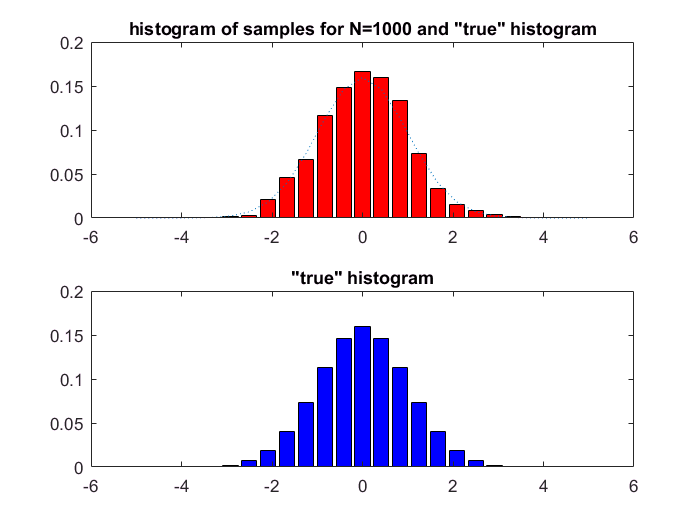

N=1000; % number of samples
y1=sqrt(sigma2)*randn(N,1)+mu*ones(N,1);
y2=hist(y1,x2);
y2=y2/sum(y2);
figure(8), subplot(2,1,1),  bar(x2,y2,'r'),hold on, plot(x2,p2,':'),hold off, title('histogram of samples for N=1000 and "true" histogram')
figure(8), subplot(2,1,2),  bar(x2,p2,'b'), title('"true" histogram')

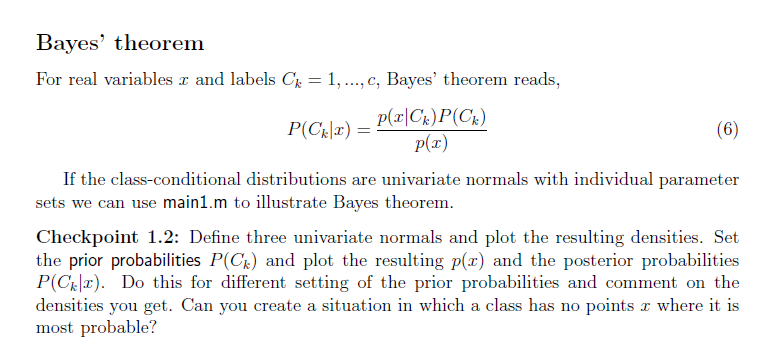

We start by defining the parameters for the three univariate normal distributions, as well as the distributions themselfs as we have seen in the previous section. 

xmin=-10;
xmax=10;
Npdf=1000;   % number of points in grid   
dx=0.4;

par1=[-2,1];    % mean value -2, variance 1
[x1,p11,x2,p12]=norm1d(par1(1),par1(2),xmin,xmax,Npdf,dx);

par2=[0,1];    % mean value 0, variance 1
[x1,p21,x2,p22]=norm1d(par2(1),par2(2),xmin,xmax,Npdf,dx);

par3=[2,1]; % mean value 2, variance 1
[x1,p31,x2,p32]=norm1d(par3(1),par3(2),xmin,xmax,Npdf,dx);

figure(3),subplot(3,1,1), plot(x1,p11,'b',x1,p21,'r',x1,p31,'g'), title('class conditional densities p(x|c)')

Now we want to represent the density of p(x). In order to do so, first we need to determine the prior probabilities.

P1=0.4; %Blue 
P2=0.3; %Red
P3=1-P1-P2; %Green

As expected, the total prior probabilities are equal 1. The density can be calculated as follows:  

px=(p11*P1+p21*P2+p31*P3);
figure(3), subplot(3,1,2), plot(x1,px,'m'), title('density p(x)')

Finally, we can calculate the posterior probabilities using the Bayes theorem 

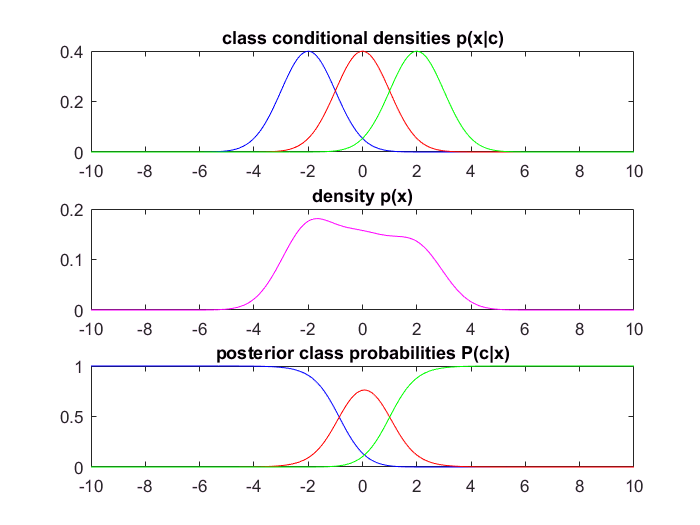

P1X=p11*P1./px;
P2X=p21*P2./px;
P3X=p31*P3./px;

figure(3), subplot(3,1,3), plot(x1,P1X,'b',x1,P2X,'r',x1,P3X,'g'),title('posterior class probabilities P(c|x)')

Different prior probabilities afect the density function as well as the posterior class probabilities, as it is expected. 

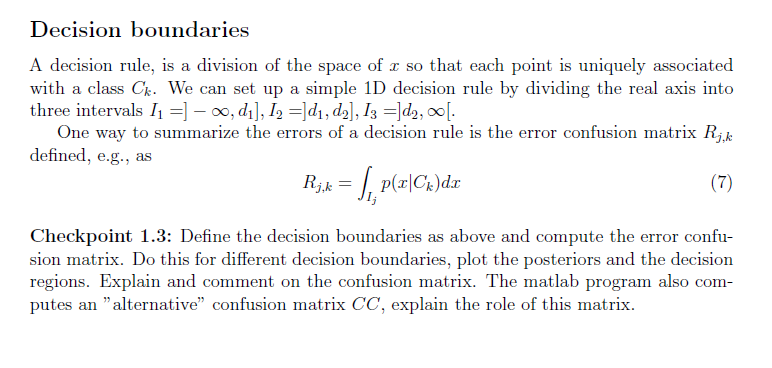

First, we need to determine the decision boundaries that we are going to use to calculate the confusion matrix.

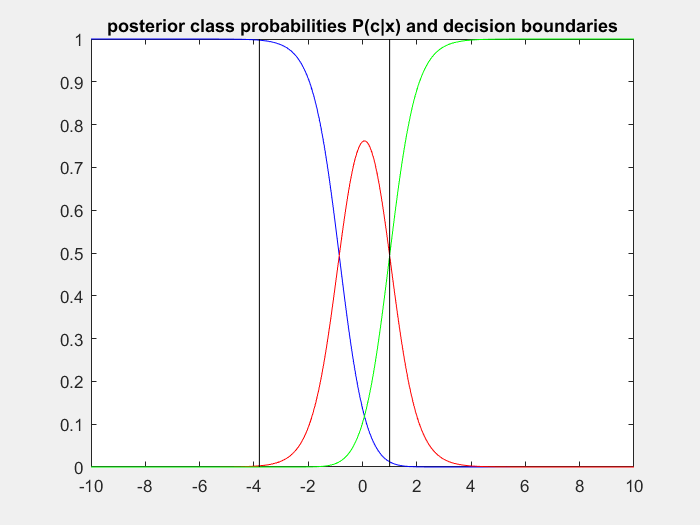

d12=-3.8;
d23=max(1.0,d12);
x12=[d12 d12];
y12=[0 1];
x23=[d23 d23];
y23=[0 1];
figure(4),  plot(x1,P1X,'b',x1,P2X,'r',x1,P3X,'g',x12,y12,'k',x23,y23,'k'),title('posterior class probabilities P(c|x) and decision boundaries')


R=probconfus(d12,d23,par1,par2,par3);
disp('The error confusion matrix is:')

The error confusion matrix is:


disp(R)

    0.0359    0.0001    0.0000
    0.9627    0.8413    0.1587
    0.0013    0.1587    0.8413



The confusion matrix interpretation is as follows: The different rows and columns represent each of the colours, blue, red and green. In the case that we find the perfect decision boundaries we will have the perfect diagonal matrix filled with ones. 

In this case, the boundaries, specially the one in the left, are pretty poorly placed, and only 0.0359 of the blue samples are classified as one of them. Most of the blue samples are classified as red, and that's why the second element of the first row is 0.9627, which makes sense when we look at the graph of the class conditional densities, as the blue distribution is almost completely on the right side of the boundary.

It is also important to note that we didn't use the posterior probabilities to calculate the confusion matrix, and thus this one is only dependent on the class conditional densities and the boundaries set (ideally you look at this graph when setting this boundaries)

CC=zeros(size(R));
CC=R*diag([P1 P2 P3]);
disp('Explain this alternative confusion matrix:')

Explain this alternative confusion matrix:


disp(CC)

    0.0144    0.0000    0.0000
    0.3851    0.2524    0.0476
    0.0005    0.0476    0.2524



In this case, this alternative confusion matrix takes into count the prior probabilities (each row is multiplied by its prior) and the sum of all this probabilities is equal to one. This can result more useful wh 